## Subscribing to VM

in this case we wanna subscribe to a topic which is active in VM

First, I tried but it did not receive any massage and timed out. The reason:

The issue is likely due to **network isolation** or an incorrect **ROS_IP** configuration. Even if MATLAB "connects" to the Master, the data streams (topics) require a bidirectional handshake where the VM must know exactly where to send the packets back to your host PC.

Check these three specific areas:

**1. The R**

**OS_IP Environment Variable**

By default, ROS nodes often use the internal loopback or a hostname the other machine can't resolve.

- **In the VM Terminal:** Run 

- `      export ROS_IP=[VM_IP_ADDRESS]` before launching `turtlesim`

-              export ROS_MASTER_URI=http://[VM_IP_ADDRESS]:11311 before launching `turtlesim`

-             rosrun turtlesim turtlesim_node __ip:=`[VM_IP_ADDRESS]`

-              to get the `[VM_IP_ADDRESS], in a terminal in VM, run: hostname -I`

- `it will be like: `

- `    export ROS_IP=192.168.64.5`

- `    export ROS_MASTER_URI=http://192.168.64.5:11311`

-         rosrun turtlesim turtlesim_node __ip:=192.168.64.5

- **In MATLAB:** Before calling `rosinit`, set the environment variable: 

-             setenv('ROS_IP', [YOUR_HOST_PC_IP]);

-             to get the 'YOUR_HOST_PC_IP', in a terminal in PC, run: ipconfig getifaddr en0

- it will be like

-         setenv('ROS_IP', '192.168.153.169');

clear all;
close all;
clc;

rosshutdown
pc_ip = '192.168.153.169'

pc_ip = '192.168.153.169'

setenv('ROS_IP', '192.168.153.169')

rosip = "192.168.153.166"; % IPv4 of the VM
port = 11311;

try
    rosinit(rosip, port)
catch er
    rosshutdown
    rosinit(rosip, port)
end

The value of the ROS_IP environment variable, 192.168.153.169, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_53532 with NodeURI http://192.168.153.169:55836/ and MasterURI http://192.168.153.166:11311.


#### Launch the turtlesim node in the VM:

roscore

rosrun turtlesim turtlesim_node __ip:=`[VM_IP_ADDRESS]`

#### Check available topics

rostopic list

/rosout              
/rosout_agg          
/tf                  
/turtle1/cmd_vel     
/turtle1/color_sensor
/turtle1/pose        


rosnode list

/matlab_global_node_53532
/rosout
/teleop_turtle
/turtlesim


rostopic echo /turtle1/pose

#### Create a subscriber that subscribes to /pose topic

pose = rossubscriber("/turtle1/pose", "DataFormat","struct");

posedata = struct with fields:
        MessageType: 'turtlesim/Pose'
                  X: 9.7110
                  Y: 7.5559
              Theta: 1.5040
     LinearVelocity: 0
    AngularVelocity: 0


#### Receive the data

posedata = receive(pose, 10)

#### Using the received data

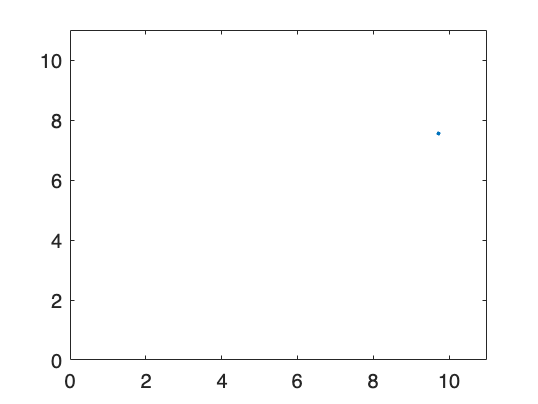

close all

figure
plot(posedata.X,posedata.Y, "Marker","*","MarkerSize",2)

xlim([0,11])
ylim([0,11])

#### Using callback

robot_pose = rossubscriber("/turtle1/pose", @T3_2_fnc, "DataFormat","struct")

robot_pose =   Subscriber with properties:

        TopicName: '/turtle1/pose'
    LatestMessage: []
      MessageType: 'turtlesim/Pose'
       BufferSize: 1
    NewMessageFcn: @T3_2_fnc
       DataFormat: 'struct'


global pos
global orient
global lin_vel
global ang_vel

for i = 1 : 10
    fprintf("\n ---------- %d ---------------- \n", i)
    pos
    orient
    lin_vel
    ang_vel
  
end


 ---------- 1 ---------------- 


pos = 1×2 single row vector
    5.1500    6.5436


orient = single
-2.9232

lin_vel = single
0

ang_vel = single
0


 ---------- 2 ---------------- 


pos = 1×2 single row vector
    5.1500    6.5436


orient = single
-2.9232

lin_vel = single
0

ang_vel = single
0


 ---------- 3 ---------------- 


pos = 1×2 single row vector
    5.1500    6.5436


orient = single
-2.9232

lin_vel = single
0

ang_vel = single
0


 ---------- 4 ---------------- 


pos = 1×2 single row vector
    5.1500    6.5436


orient = single
-2.9232

lin_vel = single
0

ang_vel = single
0


 ---------- 5 ---------------- 


pos = 1×2 single row vector
    5.1500    6.5436


orient = single
-2.9232

lin_vel = single
0

ang_vel = single
0


 ---------- 6 ---------------- 


pos = 1×2 single row vector
    5.1500    6.5436


orient = single
-2.9232

lin_vel = single
0

ang_vel = single
0


 ---------- 7 ---------------- 


pos = 1×2 single row vector
    5.1500    6.5436


orient = single
-2.9232

lin_vel = single
0

ang_vel = single
0


 ---------- 8 ---------------- 


pos = 1×2 single row vector
    5.1500    6.5436


orient = single
-2.9232

lin_vel = single
0

ang_vel = single
0


 ---------- 9 ---------------- 


pos = 1×2 single row vector
    5.1500    6.5436


orient = single
-2.9232

lin_vel = single
0

ang_vel = single
0


 ---------- 10 ---------------- 


pos = 1×2 single row vector
    5.1500    6.5436


orient = single
-2.9232

lin_vel = single
0

ang_vel = single
0

rosshutdown

Shutting down global node /matlab_global_node_53532 with NodeURI http://192.168.153.169:55836/ and MasterURI http://192.168.153.166:11311.
